clear all
data=readtable("C:\Users\thoma\Downloads\book1.xlsx")

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

           NaT    3320.3               6843.8           
    28/02/2019    3298.3               6798.3           
    27/02/2019    3282.8               6766.4           
    26/02/2019    3289.3               6779.9           
    25/02/2019      3280               6760.7           
    22/02/2019    3270.6               6741.2           
    21/02/2019    3263.7               6727.1           
    20/02/2019    3259.5               6718.4           
    19/02/2019    3239.4                 6677           
    18/02/2019    3244.8               6688.1           
    15/02/2019    3241.3               6680.8           
    14/02/2019    3182.7                 6560           
    13/02/2019    3202.4                 6599           
    12/02/2019    3190


data=flipud(data)

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

    31/12/1986    900.82               900.82           
    01/01/1987    900.82               900.82           
    02/01/1987    891.78               891.78           
    05/01/1987    898.33               898.33           
    06/01/1987    902.32               902.32           
    07/01/1987    899.15               899.15           
    08/01/1987    887.37               887.37           
    09/01/1987    868.31               868.31           
    12/01/1987    879.41               879.41           
    13/01/1987    872.74               872.74           
    14/01/1987    876.39               876.39           
    15/01/1987    884.37               884.37           
    16/01/1987    883.78               883.78           
    19/01/1987    876.

dates=datetime(data.Date,'Convertfrom','excel');
logreturn=[nan;diff(log(data.PX_LAST))]*100

logreturn =        NaN
         0
   -1.0086
    0.7318
    0.4432
   -0.3519
   -1.3188
   -2.1713
    1.2702
   -0.7614



logreturn=[nan;100*diff(log(data.PX_LAST))]

logreturn =        NaN
         0
   -1.0086
    0.7318
    0.4432
   -0.3519
   -1.3188
   -2.1713
    1.2702
   -0.7614


initialvaerdier = [0.001,1,0.05,0.9,0.0001]

initialvaerdier =     0.0010    1.0000    0.0500    0.9000    0.0001


Ovenfor=[100*nanmean(logreturn) inf 1 1 1]

Ovenfor =     1.5730       Inf    1.0000    1.0000    1.0000


any(logreturn>5)

ans = logical
   1


Nedenfor=[-nanmean(logreturn) 0 0 0 0]

Nedenfor =    -0.0157         0         0         0         0


T=size(logreturn,1)

T = 8294

A=[0 0 1 1 0];
b=1;
w = .05*.9.^(0:T-2);
backCast= w*logreturn(2:end).^2;
% backCast=0.01
options = optimset('fmincon');
options.Display = 'iter';
options.Algorithm = 'sqp';
options.Functiontolerance=1/100000000000;
options.TolCon=1/100000000000;
% options.
 estimates = fmincon(@GARCH_likelihood,initialvaerdier,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:1500),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    1.829252e+03     0.000e+00     1.000e+00     0.000e+00     6.721e+03  
    1          14    1.165634e+03     0.000e+00     4.900e-01     1.030e+00     4.063e+03  
    2          20    9.415763e+02     0.000e+00     1.000e+00     1.837e+00     2.667e+03  
    3          26    7.279685e+02     0.000e+00     1.000e+00     1.282e+00     1.390e+03  
Objective function returned NaN; trying a new point...
    4          38    7.219140e+02     0.000e+00     1.176e-01     2.485e-01     5.908e+02  
    5          53    7.148547e+02     0.000e+00     4.035e-02     2.400e-01     6.076e+02  
    6          60    6.765172e+02     0.000e+00     7.000e-01     6.448e-01     2.937e+02  
    7          69    6.701190e+02     0.000e+00     3.430e-01     2.574e-01     3.794e+02  
    8          77    6.6947

 initialvaerdier2=[estimates]

initialvaerdier2 =     0.0494    0.1086    0.2090    0.6997    0.2792


% size(GARCH_likelihood(logreturn(2:end),h,estimates,backCast))
 [estimates2,fval,exitflag,output,lambda,gradient,hessian] = fmincon(@GARCH_likelihood,initialvaerdier2,A,b,[],[],Nedenfor,Ovenfor,[],options,logreturn(2:end),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    4.947397e+03     0.000e+00     1.000e+00     0.000e+00     2.643e+03  
    1          42    4.938971e+03     0.000e+00     2.254e-05     2.951e-02     8.905e+02  
    2          58    4.935851e+03     0.000e+00     2.825e-02     4.427e-02     8.548e+02  
    3          65    4.882116e+03     0.000e+00     7.000e-01     2.695e-01     5.626e+03  
    4          72    4.846473e+03     0.000e+00     7.000e-01     5.794e-02     9.960e+03  
    5          85    4.837405e+03     0.000e+00     8.235e-02     1.075e-01     2.311e+03  
    6          96    4.827917e+03     0.000e+00     1.681e-01     7.240e-02     1.545e+03  
    7         109    4.827227e+03     0.000e+00     8.235e-02     2.016e-02     5.272e+02  
    8         117    4.821682e+03     0.000e+00     4.900e-01     6.823e-02     1.


 % % mdl=arima(data,1,0)
% % es
% % 
fval

fval = 4.8007e+03

exitflag

exitflag = 2

output

output = struct with fields:
         iterations: 24
          funcCount: 240
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-11.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   9.76e-07                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-11 (selected)'
    constrviolation: 0
           stepsize: 9.7624e-07
       lssteplength: 0.0576
      firstorderopt

lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: 0
    ineqnonlin: [0×1 double]
         lower: [5×1 double]
         upper: [5×1 double]


gradient

gradient =     0.0015
   -0.0010
   -0.0051
   -0.0058
   -0.0001


hessian

hessian = 	1.0e+05 *

    0.7330    0.4370    1.5066    1.4084    0.0193
    0.4370    4.9194    3.5096    4.5955    0.0157
    1.5066    3.5096    7.8537    8.0315    0.0565
    1.4084    4.5955    8.0315    8.8413    0.0558
    0.0193    0.0157    0.0565    0.0558    0.0006


eig(hessian)

ans = 	1.0e+06 *

    0.0000
    0.0156
    0.0441
    0.2734
    1.9018


any(eig(hessian)<=0)

ans = logical
   0


[ll,lls,h,fejlled]=GARCH_likelihood(estimates2,logreturn(2:end),backCast);
% autocorr(logreturn(2:end))
% [acf,lags,bounds]=autocorr(logreturn(2:end))
% % lmctest(h)
logreturn=logreturn/100

logreturn =        NaN
         0
   -0.0101
    0.0073
    0.0044
   -0.0035
   -0.0132
   -0.0217
    0.0127
   -0.0076


% h=h/10000
z=(logreturn(2:end)-estimates2(:,1)/100-estimates2(:,5)*sqrt(h)+h/2)./sqrt(h)

z =     0.0799
    0.0540
    0.1110
    0.1103
    0.0917
    0.0717
    0.1167
    0.2772
    0.2685
    0.2689


mean(z)

ans = 0.3186

mean(z.^2)

ans = 0.1803

mean(z.^3)

ans = 0.1569

mean(z.^4)

ans = 0.1813

% plot(z)
% [h,pValue,stat,cValue]=lbqtest(z,'lags',5)
% [h,pValue,stat,cValue]=lbqtest(z.^2,'lags',4)
h

h =     0.4896
    0.4592
    0.5507
    0.5604
    0.5371
    0.5184
    0.6815
    1.1450
    1.1889
    1.1436


standardfejl=fejlled./sqrt(h)

standardfejl =     0.0000
   -1.5717
    0.9101
    0.5166
   -0.5572
   -1.9101
   -2.6985
    1.1343
   -0.7500
    0.3375


[h,pValue,stat,cValue]=lbqtest(standardfejl,'lags',5)

h = logical
   0


pValue = 0.1859

stat = 7.5020

cValue = 11.0705

[h,pValue,stat,cValue]=lbqtest(standardfejl.^2,'lags',4)

h = logical
   0


pValue = 0.9346

stat = 0.8282

cValue = 9.4877

mean(standardfejl)

ans = -0.0396

mean(standardfejl.^2)

ans = 1.0011

mean(standardfejl.^3)

ans = -0.7486

mean(standardfejl.^4)

ans = 8.3814

% [h,p,jbstat,critval]=jbtest(standardfejl)
% [ts,pv]=ljungbox(z,12)
% [ts,pv]=lmtest(z,12,8294);
% zminus=-z.*1.96
% zplus=z.*1.96
% plot(dates(2:end),zminus,dates(2:end),zplus)
mean(standardfejl)

ans = -0.0396

mean(standardfejl.^2)

ans = 1.0011

mean(standardfejl.^3)

ans = -0.7486

mean(standardfejl.^4)

ans = 8.3814


[h,pvalue,stat,cvalue]=archtest(z)

h = logical
   1


pvalue = 0

stat = 7.8495e+03

cvalue = 3.8415

z=(logreturn(2:end)-mean(logreturn(2:end)))./sqrt(var(logreturn(2:end)))

z =    -0.0121
   -0.7873
    0.5504
    0.3286
   -0.2826
   -1.0258
   -1.6811
    0.9643
   -0.5973
    0.3087


[h,p,jbstat,critval]=jbtest(z)

h = 1

p = 1.0000e-03

jbstat = 1.2312e+04

critval = 5.9853

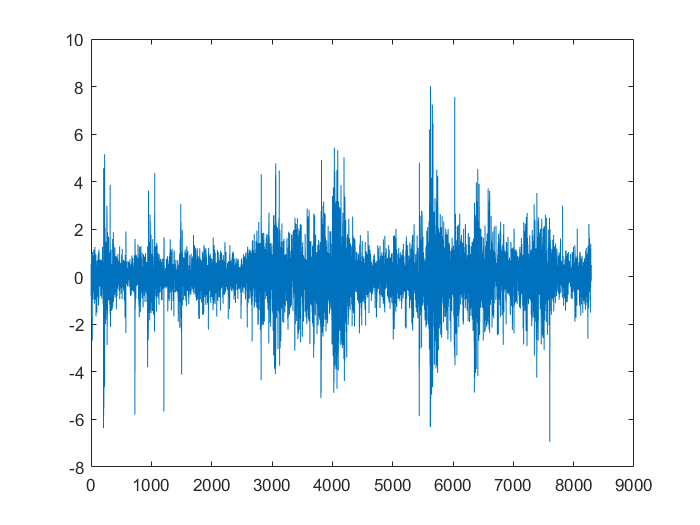


plot(z)

% [ts,pv]=ljungbox(z,12)
% [ts,pv]=lmtest(z,12,8294);
zminus=-z.*1.96

zminus =     0.0237
    1.5432
   -1.0788
   -0.6440
    0.5539
    2.0105
    3.2949
   -1.8900
    1.1707
   -0.6051


zplus=z.*1.96

zplus =    -0.0237
   -1.5432
    1.0788
    0.6440
   -0.5539
   -2.0105
   -3.2949
    1.8900
   -1.1707
    0.6051


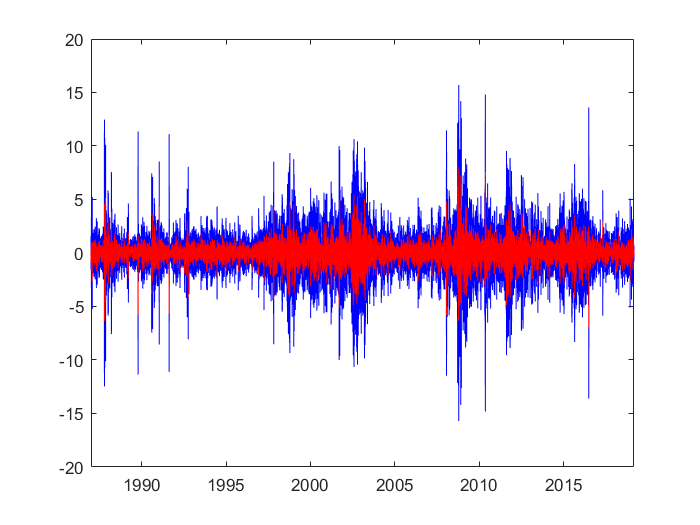

plot(dates(2:end),zminus,'blue',dates(2:end),zplus,'blue',dates(2:end),z,'red')



[h,pvalue,stat,cvalue]=archtest(z)

h = logical
   1


pvalue = 0

stat = 368.8514

cvalue = 3.8415

estimates=estimates'

estimates =     0.0494
    0.1086
    0.2090
    0.6997
    0.2792


% backCast
% sys=arx(logreturn(2:end),1);
% size(sys)
% sys=arx(logreturn(2:end),1,1,2);
% size(sys)
% resid(logreturn(2:end),sys)
%  data=logreturn(2:end)
 

%  sys=GARCH_likelihood(estimates,logreturn(2:end),backCast)
%  size(sys)
%  sys=h(2:end)
%  resid(logreturn(2:end),sys)
%  sys(:,:)
%  sys=arima(1,1,0)
%  est=estimate(sys,data)
%  size(sys)
%  resid(logreturn(2:end),sys)
% resid(logreturn(2:end),GARCH_likelihood(h,length(T),backCast))
 estimates(4)

ans = 0.6997

 estimates(3)

ans = 0.2090

%  fejlled.*h
% h(2:end)
% logreturn(3:end)
% size(h)
% size(logreturn)
% size(h(2:end))
% size(logreturn(3:end))
% mean(logreturn(2:end))
% data=logreturn(2:end,1)
% mean(fejlled.*sqrt(h)+estimates(:,2))
% mean((fejlled.*sqrt(h)+estimates(:,2)).^2)
% mean((fejlled.*sqrt(h)+estimates(:,2)).^3)
% mean((fejlled.*sqrt(h)+estimates(:,2)).^4)
% mean((fejlled.*sqrt(h)+estimates(:,2)).^2)
% mean((fejlled.*sqrt(h)).^3)
% mean((fejlled.*sqrt(h)).^4)
% % residual=mean((sqrt(h(1:end)).*fejlled(1:end)-mean(logreturn(2:end))))
% % var=mean((sqrt(h(1:end)).*fejlled(1:end)-mean(logreturn(2:end))).^2)
% % skewness=mean((sqrt(h(1:end)).*fejlled(1:end)-mean(logreturn(2:end))).^3)
% % kurtosis=mean((sqrt(h(1:end)).*fejlled(1:end)-mean(logreturn(2:end))).^4)
% mean(logreturn(2:end)./sqrt(h))
% mean((logreturn(2:end)./sqrt(h)).^2)
% mean((logreturn(2:end)./sqrt(h)).^3)
% mean((logreturn(2:end)./sqrt(h)).^4)

% residuals=(sqrt(h(1:end)).*fejlled(1:end)-mean(logreturn(2:end)));
% varresiduals=(sqrt(h(1:end)).*fejlled(1:end)-mean(logreturn(2:end))).^2;
% plot(residuals)
% plot(varresiduals)
% mean(h)
% var(h)
% estimates 
% sum(h-mean(h))
% mean(h-mean(h))
% sum((h-mean(h)).^2)
% mean((h-mean(h)).^2)
% % sum((h-mean(h)).^(3/2))
% sum((h-mean(h)).^3)
% mean((h-mean(h)).^3)
% sum((h-mean(h)).^4)
% mean((h-mean(h)).^4)
% sum(logreturn(2:end)-fejlled)/T

% residuals1=mean(h(1:end)-mean(logreturn(2:end)))
% residuals
%  resid(logreturn,h(2:end))
% 
% h
% lls
% mean(lls)
% mean(ll)
% mean(h)
% rest=sum(h(2:end)-logreturn(3:end).^2*0.01)/T
% var=sum(((h(2:end)-logreturn(3:end).^2*0.01)).^2)/T
% skew=sum(((h(2:end)-logreturn(3:end).^2*0.01)).^3)/T
% kurtosis=sum(((h(2:end)-logreturn(3:end).^2*.01)).^4)/T
% 
% %approximation af differentialet for at beregne varians
% forskel=0.00001*estimates2
% antal=length(estimates2)
% bidrag=zeros(T-1,antal);
% for i=1:antal
%     j=forskel(i);
%     delta=zeros(1,antal);
%     delta(i)=j;
%     [~, loglikelidtover]= GARCH_likelihood(estimates2+delta,logreturn(2:end),backCast);
%     [~, loglikelidtunder]=GARCH_likelihood(estimates2-delta,logreturn(2:end),backCast);
%     bidrag(:,i)=(loglikelidtover-loglikelidtunder)/(2*j)
%     %     J_i=bidrag(i)*bidrag(i)'
% end
% I=bidrag'*bidrag/T
% %Så skal J findes
% J=hessian_beggesider(@GARCH_likelihood, estimates2, logreturn(2:end), backCast)
% J=J/T
% Jinv=J\eye(length(J))
% 
% % Så kombineres J og I ved sandwhichformlen
% vcv=Jinv*I*Jinv/T
% se=sqrt(diag(vcv))
% estimates2
name={'a';'b';'c';'d'};
beta=estimates2(:,4)

beta = 0.8791

alpha=estimates2(:,3)

alpha = 0.1042

c=estimates2(:,2)/(100.^2) 

c = 2.8822e-06

n=estimates2(:,1)/100

n = 5.6451e-04

lambda=estimates2(:,5)

lambda = 0.2691

% 
% standardafvigelse=[se']
% parametre=[beta alpha c n]
% table(name, parametre',standardafvigelse')
% 
% %Simulation af indeksværdi
% d=trnd(1);
% tilfaeldige=trnd(8294-4,120,1000000);
sigma2=zeros(120,100000);
sigma2(1,:)=0.45/10000;
y=zeros(120,100000);
S=zeros(120,100000);
%  S(1,:)=data.PX_LAST(end);
 r=zeros(120,100000);
 m=zeros(120,100000);
 m(1,:)=1

m =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

 theta=zeros(120,100000);
 tic
for j=1:100000
    for i=2:120
        sigma2(i,j)=c+beta*sigma2(i-1,j)+alpha*(y(i-1,j))^2;
        y(i,j)=sqrt(sigma2(i,j))*trnd(8290)+n-sigma2(i,j)/2+lambda*sqrt(sigma2(i,j));
        r(i,j)=y(i,j)+r(i-1,j);
        S(i,j)=exp(r(i,j))*data.PX_LAST(end);
        theta(i,j)=(0.003/251)/sigma2(i,j)-1/2;
        m(i,j)=exp(y(i,j)*theta(i,j))/exp((1+theta(i,j))^2*sigma2(i,j)/2);

    end
end
toc

Elapsed time is 1070.955968 seconds.


% % r
K=data.PX_LAST(end)

K = 3.3203e+03

mean(prod(m(1:30,:)))

ans = 0.9734

mean(prod(m(1:60,:)))

ans = 0.9331

mean(prod(m(1:90,:)))

ans = 0.8880

mean(prod(m(1:120,:)))

ans = 0.8417

S

S = 	1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3336    0.3344    0.3308    0.3350    0.3331    0.3301    0.3317    0.3319    0.3344    0.3320    0.3326    0.3315    0.3339    0.3309    0.3313    0.3321    0.3301    0.3357    0.3322    0.3352    0.3335    0.3337    0.3318    0.3361    0.3301    0.3309    0.3301    0.3323    0.3353    0.3342    0.3351    0.3308    0.3293    0.3319    0.3359    0.3326    0.3314    0.3318    0.3334    0.3340    0.3322    0.3337    0.3348    0.3323    0.3332    0.3338    0.3289    0.3364   

option=exp(-0.00001*30).*mean(max(S(30,:)-K,0))

option = 291.2655

option2=mean(max(S(30,:)-K,0)).*mean(prod(m(30)))

option2 = 291.2149

option2=mean((max(S(30,:)-K,0)).*prod(m(30)))

option2 = 291.2149

option2=mean((max(S(30,:)-K,0)).*prod(m(1:30,:)))

option2 = 279.9658

option2=mean((max(S(30)-K,0)).*prod(m(30)))

option2 = 390.4732





option=exp(-0.00001*60)*mean(max(S(60,:)-K,0))

option = 707.3893

option2=mean(max(S(60,:)-K,0))*mean(prod(m(60)))

option2 = 701.0810

option2=mean(max(S(60,:)-K,0)).*mean(prod(m(60)))

option2 = 701.0810

option2=mean((max(S(60,:)-K,0)).*prod(m(1:60,:)))

option2 = 645.0586

option2=mean((max(S(60)-K,0)).*prod(m(60)))

option2 = 1.3311e+03




option=exp(-0.00001*90)*mean(max(S(90,:)-K,0))

option = 1.2414e+03

option2=mean(max(S(90,:)-K,0))*mean(prod(m(90)))

option2 = 1.2501e+03

option2=mean(max(S(90,:)-K,0)).*mean(prod(m(90)))

option2 = 1.2501e+03

option2=mean((max(S(90,:)-K,0)).*prod(m(1:90,:)))

option2 = 1.0645e+03

option2=mean((max(S(90)-K,0)).*prod(m(90)))

option2 = 1.1318e+03



option=exp(-0.00001*120)*mean(max(S(120,:)-K,0))

option = 1.9002e+03

option2=mean(max(S(120,:)-K,0))*mean(prod(m(120)))

option2 = 1.8998e+03

option2=mean(max(S(120,:)-K,0))*mean(prod(m(120)))

option2 = 1.8998e+03

option2=mean(max(S(120,:)-K,0)).*mean(prod(m(120)))

option2 = 1.8998e+03

option2=mean((max(S(120,:)-K,0)).*prod(m(1:120,:)))

option2 = 1.5225e+03

option2=mean((max(S(120)-K,0)).*prod(m(120)))

option2 = 1.7112e+03



% 
% option2=mean(max(S(120)-K,0))*mean(prod(m(120)))
% 



% S=900
% % any(S(30,:)<S(1,:)*1.2)
% K=S(1)
% for i=1:30
% optionspris30=mean(max(S(i+30,:)-K,0));
% end
% for i=1:60
% optionspris60=mean(max(S(i+30,:)-K,0));
% end
% for i=1:90
% optionspris90=mean(max(S(i+30,:)-K,0));
% end
% for i=1:120
% optionspris120=mean(max(S(i+30,:)-K,0));
% end
% optionspris30
% optionspris60
% optionspris90
% optionspris120
% A={optionspris30 optionspris60 optionspris90 optionspris120}

% T=30;
% % r=1.03^(1/250)-1;
% r=0;
% % x=zeros(1,1)
% syms op
% T=60;
% S0=S(1);
% d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% d2=d1-sqrt(op*T);
% c = optionspris60==S0*cdf('Normal',d1,0,1,0,3)-K*exp(-r*T)*cdf('Normal',d2,0,1,0,3)
% implieds=solve(c,op)
% 
% syms op
% T=90;
% S0=S(1);
% d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% d2=d1-sqrt(op*T);
% c = optionspris90==S0*cdf('Normal',d1,0,1,0,3)-K*exp(-r*T)*cdf('Normal',d2,0,1,0,3)
% implieds=solve(c,op)
% 
% h
% syms op
% T=120;
% S0=S(1);
% d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% d2=d1-sqrt(op*T);
% c = optionspris120==S0*cdf('Normal',d1,0,1,0,3)-K*exp(-r*T)*cdf('Normal',d2,0,1,0,3)
% implieds=solve(c,op)
% 
% syms op
% T=30;
% S0=S(1);
% d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% d2=d1-sqrt(op*T);
% c = optionspris30==S0*cdf('Normal',d1,0,1,0,3)-K*exp(-r*T)*cdf('Normal',d2,0,1,0,3)
% % s
% % S
% % sigma2
% % y
% % r
% %Hvor meget rammer modellen forbi.
% resid=zeros(0,8000);
% resl=zeros(0,8000);
% mean(S)
% for i=1:8000
%    resid= mean(S(i))-data.PX_LAST(i);
%    resl=sum(mean(S(i))-mean(data.PX_LAST(i)));
% end
% resid
% resl
% S(1000,:)-data.PX_LAST(1000,:)
% mean(S(8000,:))
% 
% plot(dates(2:1000),sqrt(h(2:1000)))
% % plot(dates(2:1000),S(2:1000,:))
% A=mean(S(:));
% % name='simuleretgarh'
% xlswrite('DATA.xlsx',A);

function [ll,lls,h,fejlled]=GARCH_likelihood(parameters, logreturn, backCast)

d=parameters(1);
c=parameters(2);
alpha=parameters(3);
beta=parameters(4);
lambda1=parameters(5);
T=size(logreturn,1);
% fejlled=logreturn - d;
h=zeros(T,1);
y=zeros(T,1);
h(1)=backCast;
fejlled=zeros(T,1);
fejlled=logreturn-d-lambda1*sqrt(h)+h/2;

for i=2:T
    h(i)=c+beta*h(i-1)+alpha*fejlled(i-1).^2;
    
end
v=length(logreturn)-length(parameters);
% if v<50
%     v = 2 + exp(v);
% else
%     v = 50 + log(v);
% end
% lls=log(1./(sqrt(pi.*h.*2).*exp(fejlled.^2./(h))))
%  lls= 0.5*(log(pi*2)+log(h)+fejlled.^2./h);
lls=1/2*(log(h)+(v+1)*log(1+fejlled.^2./(h.*(v-1))));

ll=  sum(lls);
end

%funktion til varians
function H= hessian_beggesider(funktion,parametre,varargin)
if size(parametre,2)>size(parametre,1)
    parametre=parametre';
end

f=feval(funktion,parametre,varargin{:});
h=abs(parametre)*0.00001;
parametreh=h+parametre;
h=parametreh-parametre;
h=diag(h);

antal=size(parametre);

afledtep=zeros(antal);
afledten=zeros(antal);
for i=1:antal
    afledtep(i)=feval(funktion, parametre+h(:,i),varargin{:});
    afledten(i)=feval(funktion, parametre-h(:,i),varargin{:});
end
anafledtep=zeros(antal);
anafledten=zeros(antal);

for j=1:antal
    for i=j:antal
        anafledtep(i,j)=funktion(parametre+h(:,j)+h(:,i),varargin{:});
        anafledtep(j,i)=anafledtep(i,j);
        anafledten(i,j)=funktion(parametre-h(:,j)-h(:,i),varargin{:});
        anafledten(j,i)=anafledten(i,j);
    end
end
H=zeros(antal);
diagonal=diag(h);
GH=diagonal*diagonal';
for i=1:antal
    for j=i:antal
        H(i,j)=(anafledtep(i,j)+anafledten(i,j)-afledtep(i)-afledten(i)-afledtep(j)-afledten(j)+f+f)/GH(i,j)/2;
        H(j,i)=H(i,j);
    end
end
end